# Sprawozadanie

# z Laboratorium Metod numerycznych

## Ćwiczenie 3:

## Aproksymacja i interpolacja

Autorzy: Dominik Gajda, 240661

Maksym Dmytruk, 240353

Data wykonania ćwiczenia: 02.11.2022, 09.11.2022

Data sporządzenia i oddania sprawozdania: 15.11.2022

### Część 1. Aproksymacja wielomianowa

Poniższe obliczenia przeprowadzono dla funkcji $f\left(x\right)=x\;\sin \;x\;$w przedziale [-1, 7]. Należało wygenerować funkcję przykładową przy pomocy polecenia `gen3INFcw3`:

fun1=@(x) x.*sin(x)

fun1 = function_handle with value:
    @(x)x.*sin(x)


ab=[-1,7]

ab =     -1     7


[fun1,ab]=gen3INFcw3(240661, 1) % Funkcja przykładowa wraz z przedziałem

fun1 = function_handle with value:
    @(x)x.^2.*cos(x)


ab =     -5     3


Wygenerowano przy pomocy polecenia `linspace` siatkę 401 równoodległych punktów w rozważanym przedziale

x=linspace(ab(1),ab(2),401); % Generacja siatki punktów do badań
y=fun1(x); % Obliczenie wartości badanej funkcji w punktach wyznaczonej wyżej siatki

Wielomian aproksymacyjny w Matlab-ie oblicza się przy pomocy funkcji `polyfit. `Wynik tej funkcji, to wektor współczynników wielomianu, którego wartości mogą być obliczane przy pomocy znanej z pierwszego ćwiczenia funkcji `polyval`.

Wybrano, obserwując wykresy wielomianu aproksymacyjnego na tle przybliżanej funkcji , taki stopień wielomianu aproksymacyjnego, by miał on tyle samo ekstremów w rozważanym przedziale, co badana funkcja.

N=5% Stopień wielomianu

N = 5

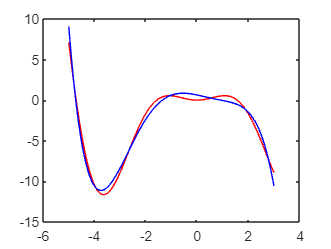

plot(x,y,'r',x,polyval(polyfit(x,y,N),x),'b')

Narysowano wykresy wielomianów aproksymacyjnych różnych stopni, z tymi samymi węzłami aproksymacji, na tle przybliżanej funkcji

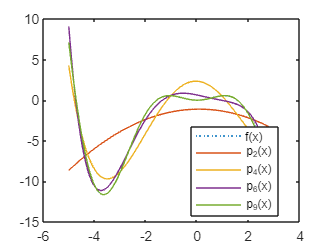

D = [2,4,6,9];
%D=3:10;
plot(x,y,':');hold on;
for k=1:length(D)
    pk=polyfit(x,y,D(k));
    y_apr=polyval(pk,x);
    plot(x,y_apr);
end
hold off;
leg=cellfun(@(n) sprintf('p_{%d}(x)',n),num2cell(D),'UniformOutput',false); % Przestudiuj dokumentację!!!
legend([{'f(x)'},leg],'Location','best')

Ponieważ na wykresie wielomiany wyższych stopni zlewają się z funkcją przybliżaną, narysować wykres wartości bezwzględnej funkcji błędu (t.j. różnicy między wielomianem aproksymacyjnym a funkcją przybliżaną) w skali półlogarytmicznej.

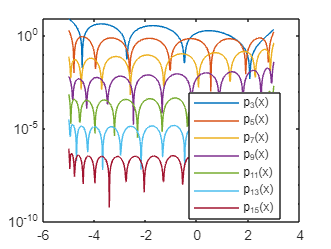

D=3:2:15;
for k=1:length(D)
    pk=polyfit(x,y,D(k));
    y_apr=polyval(pk,x);
    %plot(x,abs(y_apr-y));hold on;
    semilogy(x,abs(y_apr-y));hold on;
end
hold off;
leg=cellfun(@(n) sprintf('p_{%d}(x)',n),num2cell(D),'UniformOutput',false); % Przestudiuj dokumentację!!!
legend(leg,'Location','best')

Widać charakterystyczny kształt tych wykresów, "Ostrza" skierowane w dół odpowiadają liczbie przecięć wykresu wielomianu aproksymacyjnego i przybliżanej funkcji. **Czy da się zaobserwować wziązek liczby tych "ostrzy" ze stopniem wielomianu?**

Sporządzono wykres średniej wartości bezwzględnej błędu

D=N+2:24; % Zbiór stopni wielomianu aproksymacyjnego do przebadania
er_sr=zeros(size(D));
er_max=zeros(size(D));
new_x = x(1:2:end); %biorę każdy 2 element żeby ograniczyć ilość błędów
%new_x;
new_y = y(1:2:end); %robię to samo dla y żeby udało się wykonać funkcje polyfit
%new_y;
for k=1:length(D)
    pk=polyfit(new_x,new_y,D(k)); % Obliczenie wielomianu aproksymacyjnego danego stopnia
    y_apr=polyval(pk,new_x); % Obliczenie wielomianu aproksymacyjnego na siatce węzłów
    er_sr(k) = mean(abs(y_apr-new_y)); % Obliczenie średniej wartości bezwzględnej błędu
    er_max(k) = max(abs(y_apr-new_y)); % Obliczenie maksymalnej wartości bezwzględnej błędu
end

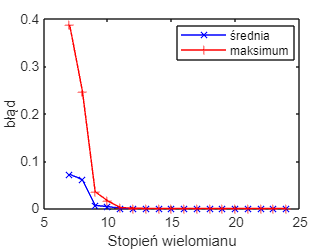

plot(D,er_sr,'bx-',D,er_max,'r+-')
xlabel('Stopień wielomianu');ylabel('błąd')
legend('średnia','maksimum','Location','best')

Dla dużych stopni wielomianu aproksymacyjnego pojawiają się ostrzeżenia! **Dlaczego?**

Ograniczyć największy badany stopień wielomianu tak, aby liczba komunikatów nie przekraczała 10.

Zwróć uwagę, że wykres maksimum błędu ma charakter schodkowy w pewnym przedziale.

Wykres dla większych wartości stopnia wielomianu jest niezbyt czytelny. Powtórzono rysowanie wykresu, stosując skalę logarytmiczną na osi rzędnych

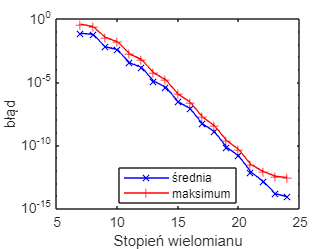

semilogy(D,er_sr,'bx-',D,er_max,'r+-')
xlabel('Stopień wielomianu');ylabel('błąd')
legend('średnia','maksimum','Location','best')

Ustalono stopień wielomianu na taki, który "wizualnie" dobrze oddaje kształt funkcji i sporządzić wykres maksymalnej wartości błędu w funkcji liczby węzłów użytych do aproksymacji

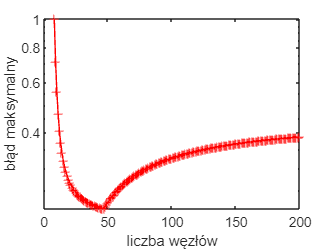

W=N+3:200; % Wektor z liczbami węzłów, które mają być przebadane
er_max=zeros(size(W));
for k=1:length(W)
    w=linspace(ab(1),ab(2),W(k)); % Wygenerowanie siatki W(k) węzłów
    pk=polyfit(w,fun1(w),N+2); % Obliczenie wielomianu aproksymacyjnego na tej siatce
    y_apr=polyval(pk,x); % Obliczenie wielomianu aproksymacyjnego na siatce węzłów
    er_max(k) = max(abs(y_apr-y)); % Obliczenie maksymalnej wartości bezwzględnej błędu
end
semilogy(W,er_max,'r+-')
xlabel('liczba węzłów');ylabel('błąd maksymalny')

#### Obserwacje

### Część 2. Aproksymacja średniokwadratowa dowolnymi funkcjami

Rozwiązać liniowe zadanie aproksymacji średniokwadratowej danych, zawierających lisowe zaburzenia (na przykład błędy pomiarowe), funkcją postaci:


$$f\left(x\right)=a\;e^x +b\;x+c$$


Korzystając z funkcji `dot`, albo mnożenia przez wektor transponowany, obliczyć gramian i wektor prawych stron dla zadania aprokymacji funkcją powyżej wypisanej postaci i rozwiązać układ równań normalnych:


$$\left\lbrack \begin{array}{ccc}
\left\langle \varphi_1 ,\varphi_1 \right\rangle  & \left\langle \varphi_1 ,\varphi_2 \right\rangle  & \left\langle \varphi_1 ,\varphi_3 \right\rangle \\
\left\langle \varphi_2 ,\varphi_1 \right\rangle  & \left\langle \varphi_2 ,\varphi_2 \right\rangle  & \left\langle \varphi_2 ,\varphi_3 \right\rangle \\
\left\langle \varphi_3 ,\varphi_1 \right\rangle  & \left\langle \varphi_3 ,\varphi_2 \right\rangle  & \left\langle \varphi_3 ,\varphi_3 \right\rangle 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
a\\
b\\
c
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left\langle \varphi_1 ,y\right\rangle \\
\left\langle \varphi_2 ,y\right\rangle \\
\left\langle \varphi_3 ,y\right\rangle 
\end{array}\right\rbrack$$


($y\left(x\right)$ oznacza tu funkcję przybliżaną, a ponadto $\varphi_1 \left(x\right)=e^x ,\varphi_2 \left(x\right)=x,\varphi_3 \left(x\right)\equiv 1$ 

Jeśli znany jest charakter zależności $y(x)$, to rozwiązanie takiego zadania może posłużyć do wyznaczenia jakiegoś parametru systemu, którego pomiary analizujemy. Jeśli brak teorii, pozwalającej wybrać funkcje bazowe, to taka aproksymacja pozwala "wygładzić" dane pomiarowe.

[x,y]=gen3INFcw3(240661,2); % Wczytać zbiór danych do aproksymacji
% x jest wektorem wartości zmiennej niezależnej (węzłami), y wektorem
% odpowiadających im wartości funkcji przybliżanej

M=[exp(x);x;ones(size(x))];
dot_product = dot(M,M)

dot_product =     2.0000    2.2314    2.5318    2.9121    3.3855    3.9683    4.6801    5.5452    6.5930    7.8596    9.3891   11.2350   13.4632   16.1537   19.4046   23.3355   28.0925   33.8541   40.8382   49.3112   59.5982


for i=1:3
    for j=1:21
        new_Gramian(i,j) = dot(M(i,j),M(i,j));
    end
end
new_Gramian 

new_Gramian =     1.0000    1.2214    1.4918    1.8221    2.2255    2.7183    3.3201    4.0552    4.9530    6.0496    7.3891    9.0250   11.0232   13.4637   16.4446   20.0855   24.5325   29.9641   36.5982   44.7012   54.5982
         0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


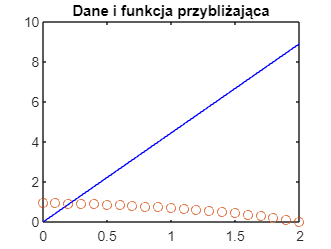

Gramian=M.*M; % Obliczenie (zestawienie) Gramianu chyba było M*M
Gramian;
RHS=M*y'; % Obliczenie wektora prawych stron
abc=Gramian\RHS; % Obliczenie wektora współczynników
plot(x,abc(1)*exp(x)+abc(2)*x+abc(3),'b-',x,y,'o') % Wykres funkcji przybliżającej na tle danych
title('Dane i funkcja przybliżająca')

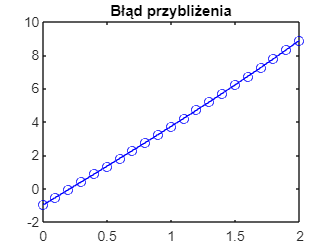

plot(x,abc(1)*exp(x)+abc(2)*x+abc(3)-y,'bo-')
title('Błąd przybliżenia')

#### Obserwacje

Można zauważyć że funkcja przybliżająca ma najmniejszy błąd gdzięś od punktu 5.8 i do 8.

#### Uwagi i wnioski

### Część 3. Interpolacja wielomianowa

#### Interpolacja z węzłami równodległymi

Obliczono wielomiany interpolacyjne różnych stopni dla funkcji badanej w części pierwszej

[fun1,ab]=gen3INFcw3(240661, 1) % Funkcja przykładowa wraz z przedziałem

fun1 = function_handle with value:
    @(x)x.^2.*cos(x)


ab =     -5     3


x=linspace(ab(1),ab(2),1001); % Wygenerowanie siatki do obserwacji wyników
y=fun1(x); % Obliczenie funkcji na "gęstej" siatce punktów

Do obliczania współczynników wielomianu interpolacyjnego może posłużyć funkcja polyfit, jeśli stopień wielomianu przybliżającego będzie o 1 mniejszy od liczby węzłów.

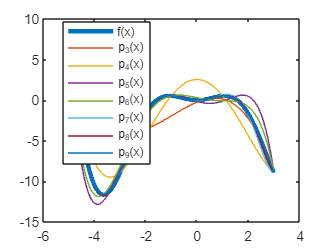

D=3:9; % Wektor badanych stopni wielomianu interpolacyjnego
plot(x,y,'Linewidth',3);hold on;
for k=1:length(D)
    w=linspace(ab(1),ab(2), D(k)+1); % Wygenerowanie węzłów dla wielomianu interpolacyjnego
    pk=polyfit(w,fun1(w),D(k)); % Obliczenie współczynników wielomianu
    % interpolacyjnego
    plot(x,polyval(pk,x));
end
hold off;
leg=cellfun(@(n) sprintf('p_{%d}(x)',n),num2cell(D),'UniformOutput',false);
% Przestudiuj dokumentację!!!
legend([{'f(x)'},leg],'Location','best')

Podobnie jak przy aproksymacji można narysować wykresy funkcji błędu:

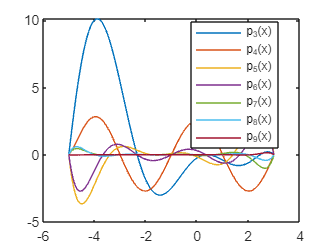

for k=1:length(D)
    w=linspace(ab(1),ab(2),D(k)+1); % Wygenerowanie węzłów dla wielomianu interpolacyjnego
    pk=polyfit(w,fun1(w), D(k)); % Obliczenie współczynników wielomianu interpolacyjnego
    plot(x,polyval(pk,x)-y);hold on;
end
hold off;
leg=cellfun(@(n) sprintf('p_{%d}(x)',n),num2cell(D),'UniformOutput',false); % Przestudiuj dokumentację!!!
legend(leg,'Location','best')

Podobnie jak przy aproksymacji, można wykres modułu funkcji błędu sporządzić w skali półlogarytmicznej:

D=4:3:19;
for k=1:length(D)
    w=linspace(ab(1),ab(2),D(k)+1); % Wygenerowanie węzłów dla wielomianu interpolacyjnego
    pk=polyfit(w,fun1(w), D(k)); % Obliczenie współczynników wielomianu interpolacyjnego
    semilogy(x,abs(polyval(pk,x)-y));hold on;
end

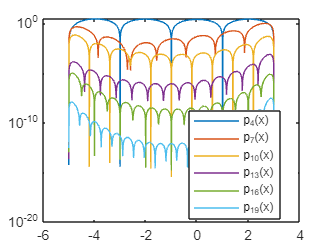

hold off;
leg=cellfun(@(n) sprintf('p_{%d}(x)',n),num2cell(D),'UniformOutput',false); % Przestudiuj dokumentację!!!
legend(leg,'Location','best')

Teraz liczbę "ostrzy" skierowanych w dół można przewidzieć: będzie nie mniejsza niż stopień wielomianu powiększony o 1.

W przypadku zwiększenia maksymalnego stopnia wielomianu do 19 pojawia się ostrzeżenie spowodowane rozwiązywaniem źle uwarunkowanej macierzy Vandermode'a.

#### Interpolacja rodziną trójkątną wielomianów

Zakłada się, że x to węzły, c współczynniki wielomianów rodziny trójkątnej, a t wektor wartości zmiennej niezależnej, dla których ma zostać obliczony wielomian

Rodzina trójkątna dla układu $n$ węzłów ma postać


$$\left\lbrack \begin{array}{c}
1\\
x-x_1 \\
\left(x-x_1 \right)\left(x-x_2 \right)\\
\vdots \\
\prod_{k=1}^{n-1} \left(x-x_k \right)
\end{array}\right\rbrack$$


Jeśli przez $y_1 ,y_2 ,y_3 ,y_4$ oznaczymy wartości funkcji interpolowanej w węzłach, a przez $c_1 ,c_2 ,c_3 ,c_4$ współczynniki, z jakimi wielomiany rodziny trójkątnej wchodzą do wielomianu interpolacyjnego, to układ równań przyjmie postać


$$\left\lbrack \begin{array}{ccccc}
1 & 0 & \cdots  & \cdots  & 0\\
1 & x_2 -x_1  & \ddots  & \; & \vdots \\
1 & x_3 -x_1  & \left(x_3 -x_1 \right)\left(x_3 -x_2 \right) & \ddots  & \vdots \\
\vdots  & \vdots  & \vdots  & \ddots  & 0\\
1 & x_n -x_1  & \left(x_n -x_1 \right)\left(x_n -x_2 \right) & \cdots  & \prod_{k=1}^{n-1} \left(x_n -x_k \right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
c_2 \\
c_3 \\
\vdots \\
c_n 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 \\
\vdots \\
y_n 
\end{array}\right\rbrack$$


Napisano dwie funkcje: obliczającą współczynniki wielomianu interpolacyjnego `c=tri_fam_coef(x,y)` oraz obliczającą wartości wielomianu `z=tri_fam_val(c,x,t)`. Użytecznym narzędziem do zbudowania macierzy układu równań wypisanej powyżej jest funkcja `cumprod.` Układ równań można rozwiązano implementując podstawienie w przód jako metodę rozwiązania układu z macierzą trójkątną dolną, z jaką mamy tu do czynienia.

Obliczanie wielomianu przeprowadzono w sposób naśladujący schemat Hornera, tzn.


$$z=\left(\left(\cdots \left(\left(c_n \left(t-x_{n-1} \right)+c_{n-1} \right)\left(t-x_{n-2} \right)+c_{n-2} \right)\cdots \right)\left(t-x_2 \right)+c_2 \right)\left(t-x_1 \right)+c_1$$


Napisano skrypt obliczający macierz i prawą stronę układu równań dla interpolacji rodziną trójkątną, a następnie, po przetestowaniu, skopiowano do następnej sekcji i przekształć przy pomocy opcji menu kontekstowego *"Convert to local function"* do funkcji `c=tri_fam_coef(x,y)`

N = 10;
x = 1:N;
y = randn(1,N);

%%%%%%%%%%%%%%%%%%%%%
% c=tri_fam_coef(x,y)
%%%%%%%%%%%%%%%%%%%%%
y = y(:);
x = x(:);
merged = [ones(length(x),1), x-x(1:end-1)'];
Xp = cumprod(merged,2);
c = Xp\y;
%%%%%%%%%%%%%%%%%%%%%

c = tri_fam_coef(x, y);

Powtórzono to samo z obliczaniem wartości wielomianu interpolacyjnego uzyskanego przy pomocy rodziny trójkątnej

N = 10;
x = 1:N;
t = 10 * rand(1,N); % wektor zmiennej niezależnej


%%%%%%%%%%%%%%%%%%%%%
% z=tri_fam_val(c,x,t)
%%%%%%%%%%%%%%%%%%%%%
n=length(x)-1; % Odczytanie stopnia wielomianu
tmp = c(n); % zaincjowanie zmiennej pomocniczej
% odpowiadającej zawartości najbardziej wewnętrz
for k=n-1:-1:1
    tmp = tmp .* (t - x(k) + c(k)); % Aktualizacja zmiennej pomocniczej
end
z = tmp;
%%%%%%%%%%%%%%%%%%%%%

z = tri_fam_val(c, x, t)

z =    -1.2326    0.3442  -77.2101   -1.1517   -0.1680   -1.9644    2.8549  -13.1979    3.3125   -0.9926


Przetestowano te funkcje porównując ją z parą funkcji `polyfit` i `polyval` dla wielomianu interpolacyjnego stopnia 9 dla funkcji padanej w części pierwszej.

fun1=@(x) x.*sin(x)  % Przywołanie funkcji testowej

fun1 = function_handle with value:
    @(x)x.*sin(x)


ab=[-1,7]            % Przedział w którym badamy funkcję

ab =     -1     7


N=9;                 % Stopień wielomianu interpolacyjnego
[fun1,ab]=gen3INFcw3(240661, 1) % Funkcja przykładowa wraz z przedziałem

fun1 = function_handle with value:
    @(x)x.^2.*cos(x)


ab =     -5     3


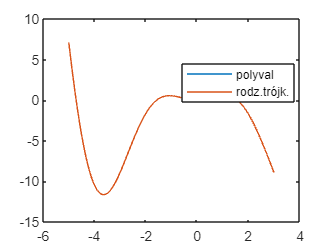

x=linspace(ab(1),ab(2),1001); % Wygenerowanie siatki do porównania wyników
w=fliplr(linspace(ab(1),ab(2),N+1)); % Wygenerowanie węzłów dla wielomianu interpolacyjnego
p=polyfit(w,fun1(w),N); % Obliczenie wielomianu interpolacyjnego funkcją wbudowaną
c=tri_fam_coef(w,fun1(w)); % Obliczenie współczynników rodziny trójkątnej
plot(x,polyval(p,x),x,tri_fam_val(c,w,x)); % Wykres wielomianu interpolacyjnego obliczonego dwiema metodami
legend('polyval','rodz.trójk.')
legend("Position", [0.57058,0.60435,0.2993,0.12695])

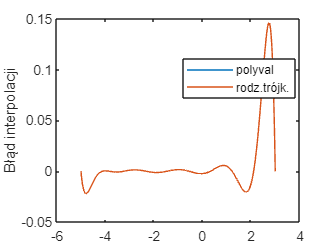

plot(x,polyval(p,x)-fun1(x),x,tri_fam_val(c,w,x)-fun1(x));
ylabel('Błąd interpolacji')
legend('polyval','rodz.trójk.')
legend("Position", [0.57319,0.62171,0.2993,0.12695])

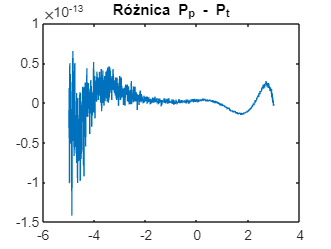

plot(x,polyval(p,x)-tri_fam_val(c,w,x));
title('Różnica P_p - P_t')

Wykresy powinny się pokrywać. Można narysować różnicę tych funkcji przybliżających. Mimo, że to ten sam wielomian, obliczany różnymi sposobami, powinna być zauważalna różnica.

#### Obserwacja zjawiska Rungego.

Wczytano drugą funkcję testową, przeznaczoną do obserwacji zjawiska Rungego

funR=@(x) exp(-x.^4)

funR = function_handle with value:
    @(x)exp(-x.^4)


abR=[-2,3]

abR =     -2     3


[funR,abR]=gen3INFcw3(240661, 3) % Funkcja przykładowa wraz z przedziałem

funR = function_handle with value:
    @(x)x./sqrt(1+x.^2)


abR =     -4     6


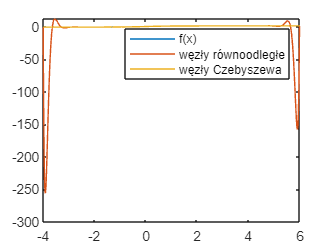

N=28; % Stopień wielomianu do obserwacji zjawiska Rungego
wR=linspace(abR(1),abR(2),N+1); % Węzły interpolacji (równoodległe)
wC=chebnodes(N+1,abR(1),abR(2)); % Węzły Czebyszewa
x=linspace(abR(1),abR(2),1001); % Siatka punktów do obserwacji jakości przybliżenia
pR=tri_fam_coef(wR,funR(wR)); % Obliczenie wielomianu z węzłami równoodległymi
pC=tri_fam_coef(wC,funR(wC)); % Obliczenie wielomianu z węzłami Czebyszewa
plot(x,funR(x),x,tri_fam_val(pR, wR, x),x,tri_fam_val(pC, wC, x))
legend('f(x)','węzły równoodległe','węzły Czebyszewa')

#### Obserwacje

Wraz ze wzrostem stopnia wielomianu, dochodzi do nagłego wzrostu wartości wielomianu interpolacyjnego na krańcach przedziałów. Efektu tego nie zaobserwowano dla interpolacji bazującej na węzłach Czebyszewa.

### Uwagi i wnioski

Interpolacja rodziną trójkątną wielomianów daje zbieżne wyniki z wynikami funkcji wbudowanej `polyval,` nie jest jednak to ta sama funkcja, co można wywnioskować z niezerowej różnicy wyników obu metod.

W celu zminimalizowania wpływu zjawiska Rungego, należy skorzystać z węzłów Czebyszewa.

Jakiejkolwiek byśmy nie wybrali strategii rozmieszczania węzłów, jeśli ich liczba będzie dążyła do nieskończoności, to znajdzie się funkcja ciągła do której ciąg wielomianów interpolacyjnych nie będzie zbieżny mimo twierdzenia Weietrstrassa. Pod tym względem węzły Czebyszewa są najlepsze, ponieważ funkcja błędu jest ograniczona przez 5ln(n+1), jest wystarczająca dla większości funkcji.

function c = tri_fam_coef(x, y)
% x - wektor węzłów funkcji
% y - wektor wartości funkcji interpolowanej w węzłach
y = y(:);
x = x(:);
merged = [ones(length(x),1), x-x(1:end-1)'];
Xp = cumprod(merged,2);
%c = Xp\y;
c = forward_sub(Xp,y); % skorzystano z rozwiązywania macierzy
% poprzez podstawienie w przód
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function c = forward_sub(A, b)
[n,m]=size(A);
[nb,~]=size(b);
if n~=m, error("Macierz A musi być kwadratowa"); end 
if n~=nb, error("Macierz A i b muszą mieć tyle samo wierszy"); end
c=zeros(size(b));
c(1,:)=b(1)/A(1,1);
for k=2:1:n
 c(k,:)=(b(k)-A(k,1:k-1)*c(1:k-1,:))/A(k,k); 
end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%

function z = tri_fam_val(c, x, t)
% c - wektor współczynników wielomianu iterpolacyjnego
% x - wektor węzłów wielomianu
% t - wektor zmiennej niezależnej
n=length(x); % Odczytanie stopnia wielomianu
tmp = c(n); % zaincjowanie zmiennej pomocniczej
% odpowiadającej zawartości najbardziej wewnętrz
for k=n-1:-1:1
    tmp = tmp .* (t - x(k)) + c(k); % Aktualizacja zmiennej pomocniczej
end
z = tmp;
end